## **Set paths**

cavemove_dataset_path = 'path/to/cavemove/dataset';
car_names = ["Volkswagen_Golf", "AlfaRomeo_146", "Smart_forfour"];
car_path = ([cavemove_dataset_path '\' car_names{1} '\']);

voice_path = 'Speech_mono_16KHz.wav';
radio_path = 'Music_mono_16KHz.wav';

## **Create Car object**

help car

 
 car
 
    A class to represent a car and the recordings associated with it.
    The class provides methods to load and process the recordings.
 
    Input:
        path (char)   - The path to the folder with the recordings for the particular car.
        fs (char)     - The sampling frequency of the recordings. Default is 16000 Hz.
 
    Example:
        my_car = car(path=car_path, fs=sampling_rate);

    Documentation for car



my_car = car("path",car_path,"fs",16000)

my_car =   car with properties:

            correction_lin: [8×1 double]
                        fs: 16000
                       irs: [1×1 struct]
                 radio_irs: [1×1 struct]
          noise_recordings: [1×1 struct]
    ventilation_recordings: [1×1 struct]
                mic_setups: ["array"    "distributed"]
         speaker_locations: [1×1 struct]
                      make: 'Volkswagen'
                     model: 'Golf'
                      year: '2011'


## **Properties**

**correction_lin**

help my_car.correction_lin

--- help for car/correction_lin ---

 correction_lin -  Returns a table (1x8) with the correction gains of all microphones. (linear gains).



my_car.correction_lin

ans =     1.0958
    1.0474
    1.0239
    1.0840
    1.0000
    1.3006
    1.2463
    1.1069


**fs**

help my_car.fs

--- help for car/fs ---

 fs -  Returns the sampling frequency.



my_car.fs

ans = 16000

**irs**

help my_car.irs

--- help for car/irs ---

 irs -  Returns a struck with all the available IRs per microphone configuration.



my_car.irs.array

ans = 24×1 cell array
    {'d50_w0' }
    {'d50_w1' }
    {'d50_w2' }
    {'d50_w3' }
    {'pf60_w0'}
    {'pf60_w1'}
    {'pf60_w2'}
    {'pf60_w3'}
    {'pf80_w0'}
    {'pf80_w1'}
    {'pf80_w2'}
    {'pf80_w3'}
    {'prl_w0' }
    {'prl_w1' }
    {'prl_w2' }
    {'prl_w3' }
    {'prm_w0' }
    {'prm_w1' }
    {'prm_w2' }
    {'prm_w3' }
    {'prr_w0' }
    {'prr_w1' }
    {'prr_w2' }
    {'prr_w3' }


my_car.irs.distributed

ans = 24×1 cell array
    {'d50_w0'}
    {'d50_w1'}
    {'d50_w2'}
    {'d50_w3'}
    {'d60_w0'}
    {'d60_w1'}
    {'d60_w2'}
    {'d60_w3'}
    {'pf_w0' }
    {'pf_w1' }
    {'pf_w2' }
    {'pf_w3' }
    {'prl_w0'}
    {'prl_w1'}
    {'prl_w2'}
    {'prl_w3'}
    {'prm_w0'}
    {'prm_w1'}
    {'prm_w2'}
    {'prm_w3'}
    {'prr_w0'}
    {'prr_w1'}
    {'prr_w2'}
    {'prr_w3'}


**radio_irs**

help my_car.radio_irs

--- help for car/radio_irs ---

 radio_irs -  Returns a struck with all the available radio IRs per microphone configuration.



my_car.radio_irs.array

ans = 4×1 cell array
    {'w0'}
    {'w1'}
    {'w2'}
    {'w3'}


**noise_recordings**

help my_car.noise_recordings

--- help for car/noise_recordings ---

 noise_recordings -  Returns a struck with all the available noise recordings per microphone configuration.



my_car.noise_recordings.array

ans = 73×1 cell array
    {'s0_w0'        }
    {'s0_w1'        }
    {'s0_w2'        }
    {'s0_w3'        }
    {'s100_w0_ver1' }
    {'s100_w0_ver2' }
    {'s100_w0_ver3' }
    {'s100_w0_ver4' }
    {'s100_w1_ver1' }
    {'s100_w1_ver2' }
    {'s100_w2_ver1' }
    {'s100_w2_ver2' }
    {'s100_w2_ver3' }
    {'s100_w3_ver1' }
    {'s100_w3_ver2' }
    {'s110_w0'      }
    {'s110_w1_ver1' }
    {'s110_w1_ver2' }
    {'s110_w2_ver1' }
    {'s110_w2_ver2' }
    {'s110_w3'      }
    {'s120_w0'      }
    {'s120_w1'      }
    {'s120_w2'      }
    {'s30_w0_coarse'}
    {'s30_w1_coarse'}
    {'s30_w2_coarse'}
    {'s30_w3_coarse'}
    {'s40_w0'       }
    {'s40_w1_ver1'  }


**ventilation_recordings**

help my_car.ventilation_recordings

--- help for car/ventilation_recordings ---

 ventilation_recordings -  Returns a struck with all the available ventilation conditions recordings per microphone configuration.



my_car.ventilation_recordings.array

ans = 12×1 cell array
    {'v1_w0'}
    {'v1_w1'}
    {'v1_w2'}
    {'v1_w3'}
    {'v2_w0'}
    {'v2_w1'}
    {'v2_w2'}
    {'v2_w3'}
    {'v3_w0'}
    {'v3_w1'}
    {'v3_w2'}
    {'v3_w3'}


**mic_setups**

help my_car.mic_setups

--- help for car/mic_setups ---

 mic_setups -  Returns all the available microphones configurations.



my_car.mic_setups

ans = 1×2 string array
    "array"    "distributed"


**speaker_locations**

help my_car.speaker_locations

--- help for car/speaker_locations ---

 speaker_locations -  Returns a struck with all the available speaker locations per microphone configuration.



my_car.speaker_locations.array

ans = 6×1 cell array
    {'d50' }
    {'pf60'}
    {'pf80'}
    {'prl' }
    {'prm' }
    {'prr' }


**make**

help my_car.make

--- help for car/make ---

 make -  Returns the make of the car.



my_car.make

ans = 'Volkswagen'

**model**

help my_car.model

--- help for car/model ---

 model -  Returns the model of the car.



my_car.model

ans = 'Golf'

**year**


help my_car.year

--- help for car/year ---

 year -  Returns the year of construction of the car.



my_car.year

ans = '2011'

## `Functions`

**load_ir**

help my_car.load_ir

--- help for car/load_ir ---

 
 
 load_ir Loading impulse responses
 
    Loads the impulse response (IR) channels for a given microphone setup and IR condition.
 
    Input:
        mic_setup (char)   - The desired microphone setup to load the IR for.
        condition (char)   - The specific IR condition to load ("'speaker location'_w'window condition'").
    Output:
        ir (vector)   - Matrix NxM, containing the IR data
                        N = the number of samples, M=number of
                        microphones.
 
    Example:
        my_car = car(path=car_path, fs=sampling_rate);
        irs = my_car.load_ir("condition",'d50_w1',"mic_setup",'array');



irs = my_car.load_ir("condition",'d50_w1',"mic_setup",'array');
disp(size(irs))

        2400           8



**plot load_ir**

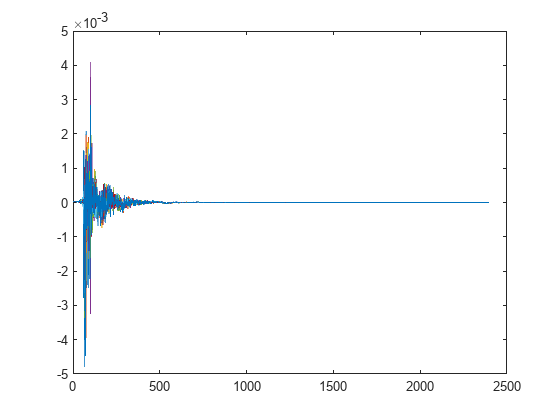

plot(irs) % 8 channels

**load_radio_ir**

help my_car.load_radio_ir

--- help for car/load_radio_ir ---

 
 load_radio_ir Loading radio impulse responses
 
    Loads the radio impulse response (IR) channels for a given
    microphone setup and radio condition.
 
    Input:
        mic_setup (char)   - The desired microphone setup to load the IR for.
        condition (char)   - The specific IR condition to load ("window condition").
    Output:
        radio_ir (vector)   - Matrix NxM, containing the radio IR data
                        N = the number of samples, M=number of
                        microphones.
    Example:
        my_car = car(path=car_path, fs=sampling_rate);
        radio_irs = my_car.load_radio_ir("condition",'w1',"mic_setup",'array');



radio_irs = my_car.load_radio_ir("condition",'w1',"mic_setup",'array');
disp(size(radio_irs))

        2400           8



**plot load_radio_ir**

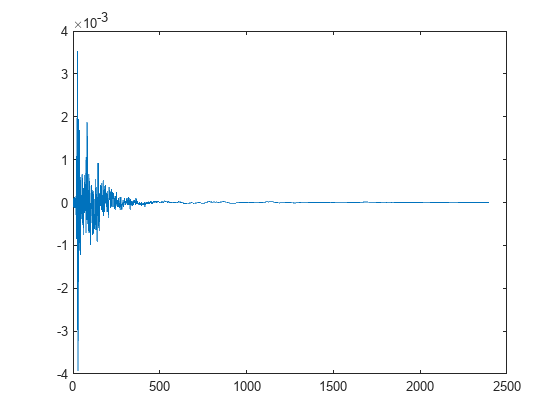

plot(radio_irs(:,5)) % one channel

**load_noise**

help my_car.load_noise

--- help for car/load_noise ---

 
 load_noise Loading noise recordings
    Loads the noise recording channels for a given microphone setup and noise condition.
 
    Input:
        mic_setup (char)   - The desired microphone setup to load the IR for.
        condition (char)   - The specific IR condition to load ("'speaker location'_w'window condition'").
    Output:
        ir (vector)   - Matrix NxM, containing the noise data
                        N = the number of samples, M=number of
                        microphones.
 
    Example:
        my_car = car(path=car_path, fs=sampling_rate);
        noise = my_car.load_noise("condition",'s90_w1_ver1',"mic_setup",'array');



noise = my_car.load_noise("condition",'s90_w1_ver1',"mic_setup",'array');
disp(size(noise))

      479273           8



**plot load_noise**

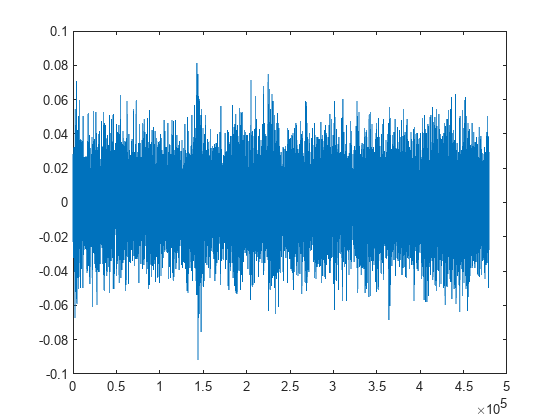

plot(noise(:,5)) % one channel

**load_ventilation**

help my_car.load_ventilation

--- help for car/load_ventilation ---

 
 load_ventilation Loading ventilation recordings
 
    Loads the ventilation recording for a given microphone
    setup and condition.            
    Input:
        mic_setup (char)   - The desired microphone setup to load the IR for.
        condition (char)   - The specific ventilation condition to load ("v'ventilation level'_w'window condition'").
    Output:
        ventilation(vector)   - Matrix NxM, containing the ventilation data
                                N = the number of samples, M=number of
                                microphones.
    Example:
        my_car = car(path=car_path, fs=sampling_rate);
        ventilation = my_car.load_ventilation("condition",'v1_w0',"mic_setup",'array');



ventilation = my_car.load_ventilation("condition",'v1_w0',"mic_setup",'array');
disp(size(ventilation))

      399090           8



**plot load_ventilation**

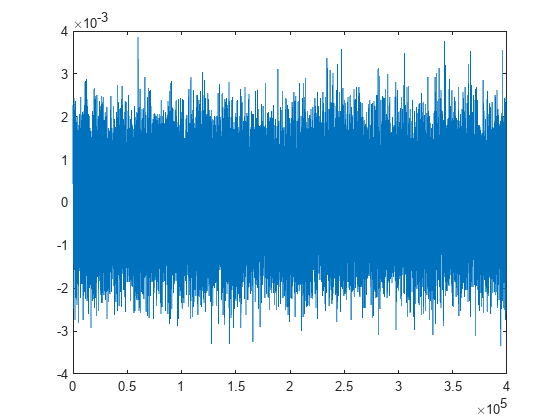

plot(ventilation(:,5)) % one channel

**get_speech**

help my_car.get_speech

--- help for car/get_speech ---

 
 get_speech Creating speech component (y=dry_speech*h_passenger)
 
    Generates the convolved speech signal with the corresponding impulse response for a given
    microphone setup, location, and condition.
 
    Input:
        mic_setup (char)   - The microphonesconfiguration to use.
        location (char)   - The location of speaker inside the car.
        window (double)   - The window condition.
        ls (double or char)   - The speech effort level.
        dry_speech (double)   - The dry speech signal in mono.
        mics (double or char, optional)   -  The microphone index or indices to use (Default=nan, all availabe microphones are used.).
        use_correction_gains (bool, optional)   -  A boolean indicating whether to use the correction gains (Default=true).
    Output:
        S (vector)   - Vector NxM, The processed speech signal.
                       N = the number of samples, M = the number of cha

[dry_voice,fs_dry_voice] = audioread(voice_path);
S = my_car.get_speech("dry_speech",dry_voice,"ls",'High',"mics",5, ...
    "location",'d50',"mic_setup",'array',"use_correction_gains",true,"window",1);
ir_S= my_car.load_ir("condition",'d50_w1',"mic_setup",'array');
ir_S_mic5 = ir_S(:,5);
disp(my_car.fs)

       16000



disp(fs_dry_voice)

       16000



**plot get_speech**

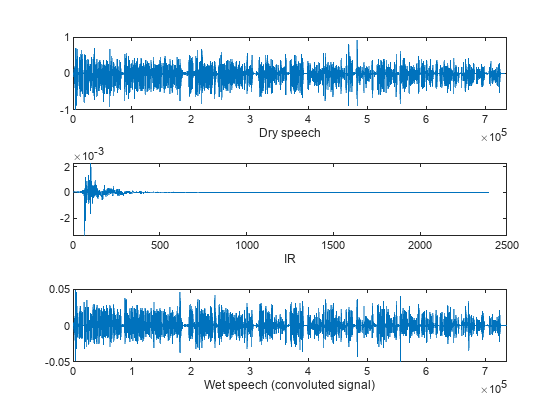

figure()
subplot(3,1,1)
plot(dry_voice)
xlabel("Dry speech")
xlim([0 length(S)])
subplot(3,1,2)
plot(ir_S_mic5)
xlabel("IR")
subplot(3,1,3)
plot(S)
xlabel("Wet speech (convoluted signal)")
xlim([0 length(S)])

**get_noise**

help my_car.get_noise

--- help for car/get_noise ---

 
 get_noise Loading noise recordings
    Retrieves the in-motion noise recording for a given microphone setup, condition, and microphone index.
 
    Input:
        mic_setup (char)   - The microphonesconfiguration to use.
        speed (double)   - The speed condition.
        window (double)   - The window condition.
        version (char, optional)   - The version of the noise recording in case there are multiple versions. Defaults to None. Must be "ver1", "ver2", etc or "coarse" (Default=nan).
        mics (double or char, optional)   - The microphone index or indices to use (Default=nan, all availabe microphones are used).
        use_correction_gains (bool, optional)   -  A boolean indicating whether to use the correction gains (Default=true).
    Output
        N (vector)   - Vector NxM, The processed noise signal.
                       N = the number of samples, M = the number of channels.
    Example:
        

N = my_car.get_noise("mic_setup",'array',"speed",100,"window",1, ...
    "use_correction_gains",true,"mics",5);
disp(size(N))

      479892           1



**plot get_noise**

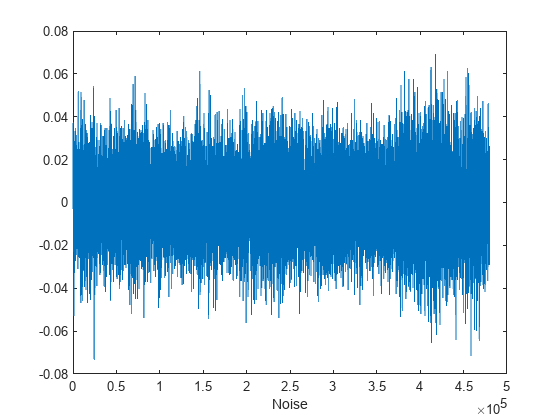

figure()
plot(N)
xlabel("Noise")

**get_radio**

help my_car.get_radio

--- help for car/get_radio ---

 
 get_radio Creating radio_component (y=dry_radio*h_radio)
    Generates the radio (car-audio) signal by exploiting the measured  impulse response for a given
    microphone setup, condition, and microphone index.
 
    Input:
        mic_setup (char)   - The configuration of microphones.
        window (double)   - The window condition.
        la (double)   - The radio audio level.
        radio_audio (double)   - The radio audio signal in mono (Default=nan).
        mics (double or char, optional)   - The microphone or microphones, which is chosen by the user.
        use_correction_gains (bool, optional)   -  A boolean indicating whether to use the correction gains (Default=true).
    Output:
        A (vector)   - Vector NxM, The processed radio signal.
                       N = the number of samples, M = the number of channels.
    Example:
        my_car = car(path=car_path, fs=sampling_rate);
        A = my_car

[radio_tune,fs_dry_radio] = audioread(radio_path);
A = my_car.get_radio("la",70,"mics",5,"radio_audio",radio_tune, ...
    "mic_setup",'array',"use_correction_gains",true,"window",1);
radio_ir_A = my_car.load_radio_ir("condition",'w1',"mic_setup",'array');
radio_ir_A_mic5 = radio_ir_A(:,5);
disp(my_car.fs)

       16000



disp(fs_dry_radio)

       16000



**plot get_radio**

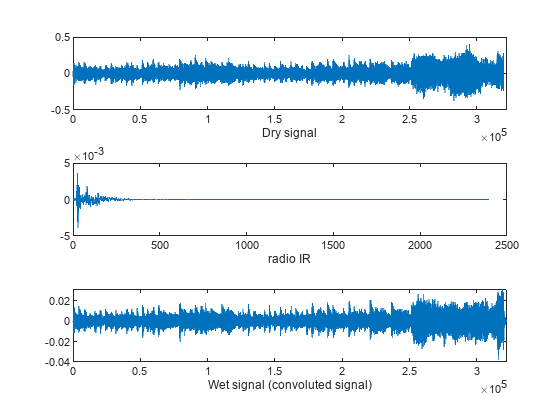

figure()
subplot(3,1,1)
plot(radio_tune)
xlabel("Dry signal")
xlim([0 length(A)])
subplot(3,1,2)
plot(radio_ir_A_mic5)
xlabel("radio IR")
subplot(3,1,3)
plot(A)
xlabel("Wet signal (convoluted signal)")
xlim([0 length(A)])

**get_ventilation**

help my_car.get_ventilation

--- help for car/get_ventilation ---

 
 get_ventilation Loading ventilation recordings
    Retrieves and processes the ventilation recording for a given
    microphone setup, condition, and ventilation level.
 
    Input:
        mic_setup (char)   - The microphonesconfiguration to use.
        window (double)   - The window condition.
        level (double)   - The ventilation level.
        version (char, optional)   - The version of the ventilation recording in case there are multiple versions. Defaults to None. Must be "ver1", "ver2", etc (Default=nan).
        mics (double or char, optional)   -  The microphone index or indices to use (Default=nan, all availabe microphones are used.).
        use_correction_gains (bool, optional)   -  A boolean indicating whether to use the correction gains (Default=true).
    Output:
        V (vector)   - Vector NxM, The processed ventilation signal for the specified microphones.
                       N = the 

V = my_car.get_ventilation("mic_setup",'array',"level",3, ...
    "window",0,"use_correction_gains",true,"mics",5);
disp(size(V))

      399062           1



**plot get_ventilation**

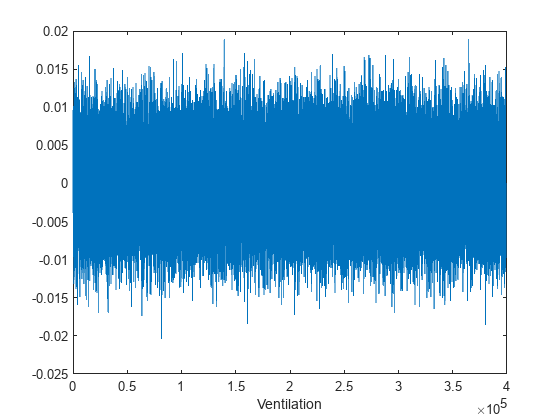

figure()
plot(V)
xlabel("Ventilation")

**match_duration**

help my_car.match_duration

--- help for car/match_duration ---

 match_duration
    Matches the duration of all input signals to the duration of the first signal.
 
    This method adjusts the duration of each input signal to match the duration of the first input signal. If a signal is longer than the first input signal, it is truncated. If an it is shorter, it is looped using crossfading to match the duration.
 
    Input:
        signal_A (double)   - The master signal.
        signal_B (double)   - The signal b.
        signal_C (double, optional)   - The signal c.
        signal_D (double, optional)   - The signal d.
    Output:
        signal_A_new (vector)   - Vector NxM, N = the number of samples, M = the number of channels.
        signal_B_new (vector)   - Vector NxM, N = length(signal_A), M = the number of channels.
        signal_C_new (vector)   - Vector NxM, N = length(signal_A), M = the number of channels.
        signal_D_new (vector)   - Vector NxM, N = length(si

[S_new,N_new,A_new,V_new] = my_car.match_duration(S,N,A,V); % S is the master.

**plot pre - match_duration**

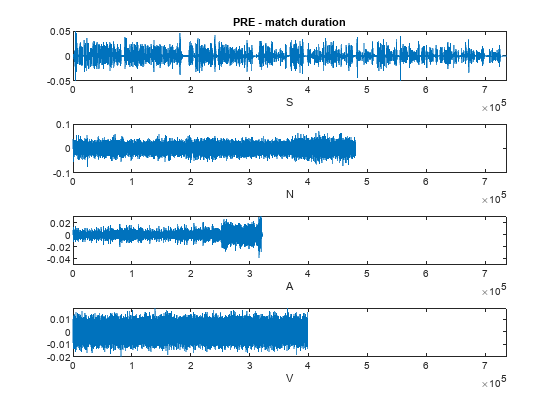

figure()
subplot(4,1,1)
plot(S)
title("PRE - match duration")
xlim([0 length(S)])
xlabel("S")
subplot(4,1,2)
plot(N)
xlim([0 length(S)])
xlabel("N")
subplot(4,1,3)
plot(A)
xlim([0 length(S)])
xlabel("A")
subplot(4,1,4)
plot(V)
xlim([0 length(S)])
xlabel("V")

**plot post - match_duration**

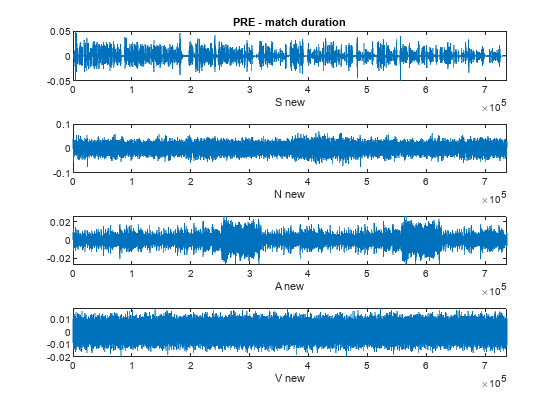

figure()
subplot(4,1,1)
plot(S_new)
title("PRE - match duration")
xlim([0 length(S)])
xlabel("S new")
subplot(4,1,2)
plot(N_new)
xlim([0 length(S)])
xlabel("N new")
subplot(4,1,3)
plot(A_new)
xlim([0 length(S)])
xlabel("A new")
subplot(4,1,4)
plot(V_new)
xlim([0 length(S)])
xlabel("V new")

**get_components**

help my_car.get_components

--- help for car/get_components ---

 get_components
    A wrapper function of the get_noise, get_speech, get_radio, and get_ventilation methods.
    Returns a matrix of components of the mixture in the following order: noise, speech, radio, ventilation.
    Speech, radio, and ventilation are optional.
 
    Input:
        mic_setup (char)   - The microphonesconfiguration to use.
        location (char)   - The location of speaker inside the car.
        speed (double)   - The speed condition.
        window (double)   - The window condition.
        version (char, optional)   - The version of the noise recording in case there are multiple versions. Defaults to None. Must be "ver1", "ver2", etc or "coarse" (Default=nan).
        mics (double or char, optional)   -  The microphone index or indices to use (Default=nan, all availabe microphones are used.).
        ls (double or char, optional)   - The speech effort level (Default=nan).
        dry_speech 

[components] = my_car.get_components( ...
    "dry_speech",dry_voice,"la",70,"ls",'High',"mics",5, ...
    "location",'d50',"radio_audio",radio_tune, ...
    "mic_setup",'array',"speed",100,"use_correction_gains",true, ...
    "vent_level",3,"window",1);
noise_sample= components(:,:,1);
speech_sample= components(:,:,2);
radio_sample= components(:,:,3); 
ventilation_sample= components(:,:,4);

**plot all components**

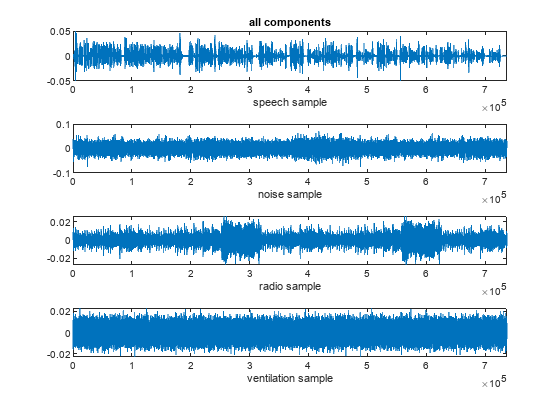

figure()
subplot(4,1,1)
plot(speech_sample)
title("all components")
xlim([0 length(speech_sample)])
xlabel("speech sample")
subplot(4,1,2)
plot(noise_sample)
xlim([0 length(speech_sample)])
xlabel("noise sample")
subplot(4,1,3)
plot(radio_sample)
xlim([0 length(speech_sample)])
xlabel("radio sample")
subplot(4,1,4)
plot(ventilation_sample)
xlim([0 length(speech_sample)])
xlabel("ventilation sample")

**get_components (without ventilation)**

[components] = my_car.get_components( ...
    "dry_speech",dry_voice,"la",70,"ls",'High',"mics",5, ...
    "location",'d50',"radio_audio",radio_tune, ...
    "mic_setup",'array',"speed",100,"window",1);
noise_sample= components(:,:,1);
speech_sample= components(:,:,2);
radio_sample= components(:,:,3); 
ventilation_sample= components(:,:,4);

**plot get_components (without ventilation)**

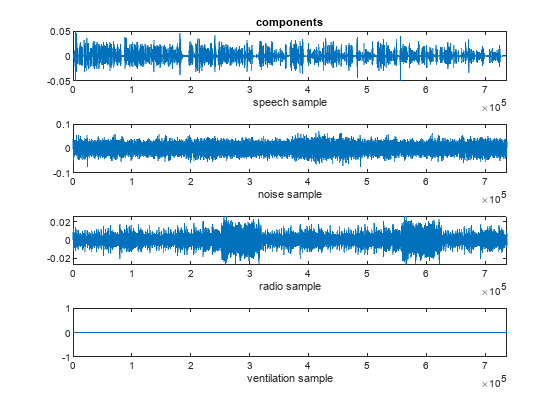

figure()
subplot(4,1,1)
plot(speech_sample)
title("components")
xlim([0 length(speech_sample)])
xlabel("speech sample")
subplot(4,1,2)
plot(noise_sample)
xlim([0 length(speech_sample)])
xlabel("noise sample")
subplot(4,1,3)
plot(radio_sample)
xlim([0 length(speech_sample)])
xlabel("radio sample")
subplot(4,1,4)
plot(ventilation_sample)
xlim([0 length(speech_sample)])
xlabel("ventilation sample")

**get_components (without radio & ventilation)**

[components] = my_car.get_components( ...
    "dry_speech",dry_voice,"ls",'High',"mics",5, ...
    "location",'d50',"mic_setup",'array',"speed",100, ...
    "window",1);
noise_sample= components(:,:,1);
speech_sample= components(:,:,2);
radio_sample= components(:,:,3); 
ventilation_sample= components(:,:,4);

**plot get_components (without radio & ventilation)**

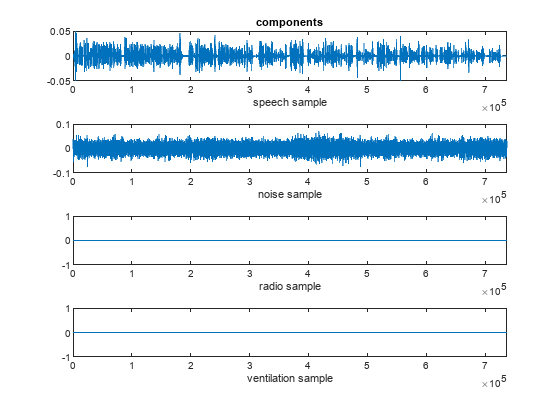

figure()
subplot(4,1,1)
plot(speech_sample)
title("components")
xlim([0 length(speech_sample)])
xlabel("speech sample")
subplot(4,1,2)
plot(noise_sample)
xlim([0 length(speech_sample)])
xlabel("noise sample")
subplot(4,1,3)
plot(radio_sample)
xlim([0 length(speech_sample)])
xlabel("radio sample")
subplot(4,1,4)
plot(ventilation_sample)
xlim([0 length(speech_sample)])
xlabel("ventilation sample")

**get_components (without speech & ventilation)**

[components] = my_car.get_components( ...
    "radio_audio",radio_tune,"la",70,"mics",5, ...
    "mic_setup",'array',"speed",100,"window",1);
noise_sample= components(:,:,1);
speech_sample= components(:,:,2);
radio_sample= components(:,:,3); 
ventilation_sample= components(:,:,4);

**plot get_components (without speech & ventilation)**

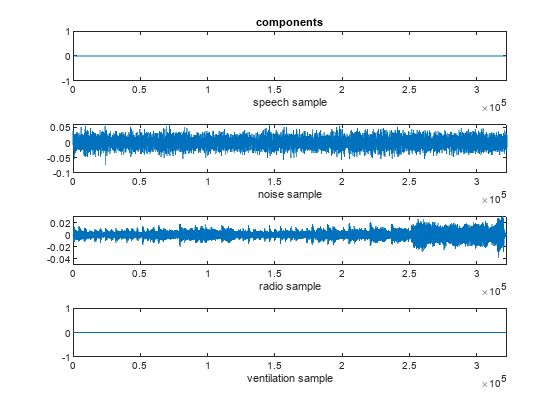

figure()
subplot(4,1,1)
plot(speech_sample)
title("components")
xlim([0 length(radio_sample)])
xlabel("speech sample")
subplot(4,1,2)
plot(noise_sample)
xlim([0 length(radio_sample)])
xlabel("noise sample")
subplot(4,1,3)
plot(radio_sample)
xlim([0 length(radio_sample)])
xlabel("radio sample")
subplot(4,1,4)
plot(ventilation_sample)
xlim([0 length(radio_sample)])
xlabel("ventilation sample")

**construct_steering_vector**

help my_car.construct_steering_vector

--- help for car/construct_steering_vector ---

 
 construct_steering_vector Constucting steering vector
    Calculates the steering vectors for a given frequency and angle, theta,  for a microphone array configuration.
    The acoustic center is defined as the center of the microphone array. 0 degrees point towards the rear middle passenger,
    so that the driver is positioned at a negative angle and the front passenger at a positive angle.
 
    Input:
        freq (double)   -  The frequency in Hz at which to calculate the steering vectors.
        theta (double)   - The angle in degrees at which to calculate the steering vectors.
    Output:
        steering_vector (complex double)   - An array of complex steering vectors for each microphone in the array.
    Example:
        my_car = car(path=car_path, fs=sampling_rate);
        sv = my_car.construct_steering_vector("freq",8000, "theta",-28)



sv = my_car.construct_steering_vector("freq",8000, "theta",-28)

sv =   -0.8322 + 0.5544i  -0.3357 - 0.9420i   0.9506 + 0.3104i   0.4210 - 0.9070i  -0.8322 - 0.5544i  -0.3357 + 0.9420i   0.9506 - 0.3104i   0.4210 + 0.9070i


**speaker_locations_angles**

help my_car.speaker_locations_angles

--- help for car/speaker_locations_angles ---

 speaker_locations_angles
    Returns the speaker locations and their corresponding
    angles with respect to the center of the microphone array.
 
    Input:
        mic_setup (char)   - The desired microphone setup to use. .
    Output:
        angles (Struct with 2 fields)   - The angles in degrees.
    Example:
        my_car = car(path=car_path, fs=sampling_rate);
        my_car.speaker_locations_angles("mic_setup",'array')



my_car.speaker_locations_angles("mic_setup",'array')

ans = struct with fields:
    location: ["d50"    "pf60"    "pf80"    "prl"    "prm"    "prr"]
     degrees: [-28 26 18 -12 0 -12]
